# Sample 8-4

## 離散コサイン変換

基底画像

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Discrete cosine transform

Basis images

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

close all

### %% DCT点数

nPoints = 4;

### %% DCT行列の計算

C = dctmtx(nPoints);

### %% 基底ベクトルの表示

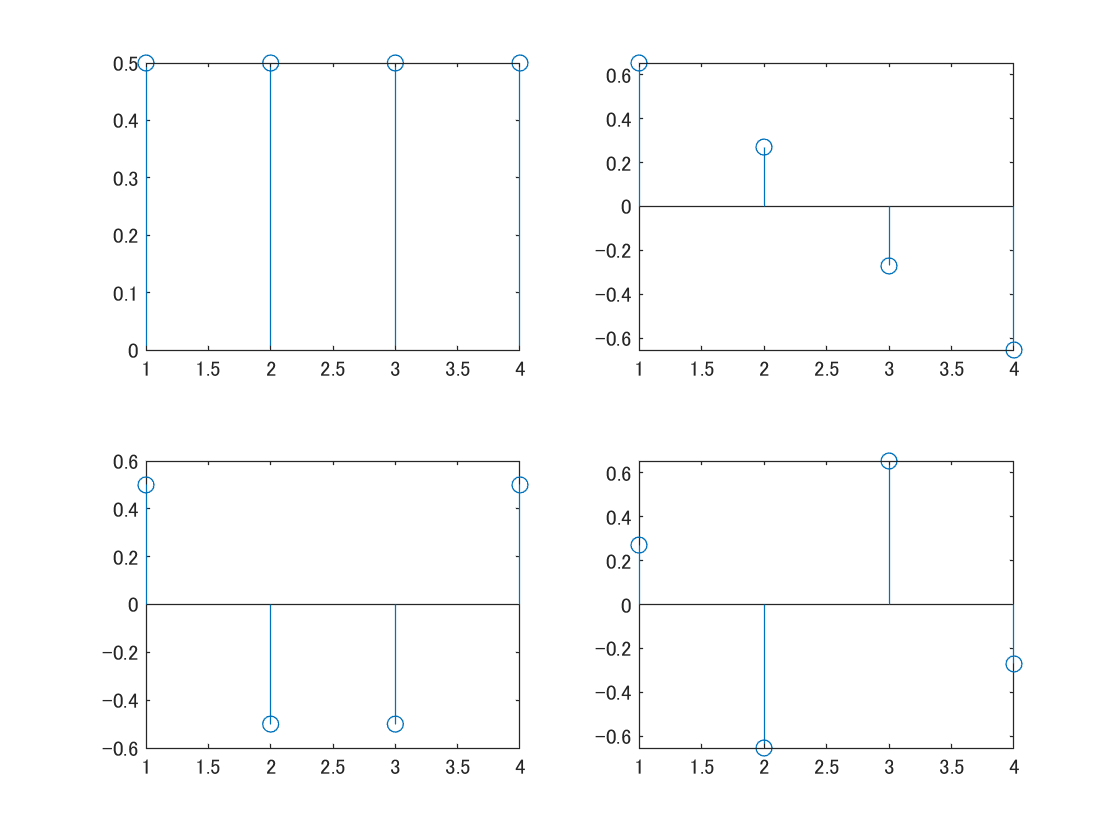

nRows = size(C,1);
figure(1);
for iRow = 1:nRows
    subplot(ceil(nRows/2),2,iRow);
    stem(C(iRow,:)); 
end;

### %% 基底画像の表示

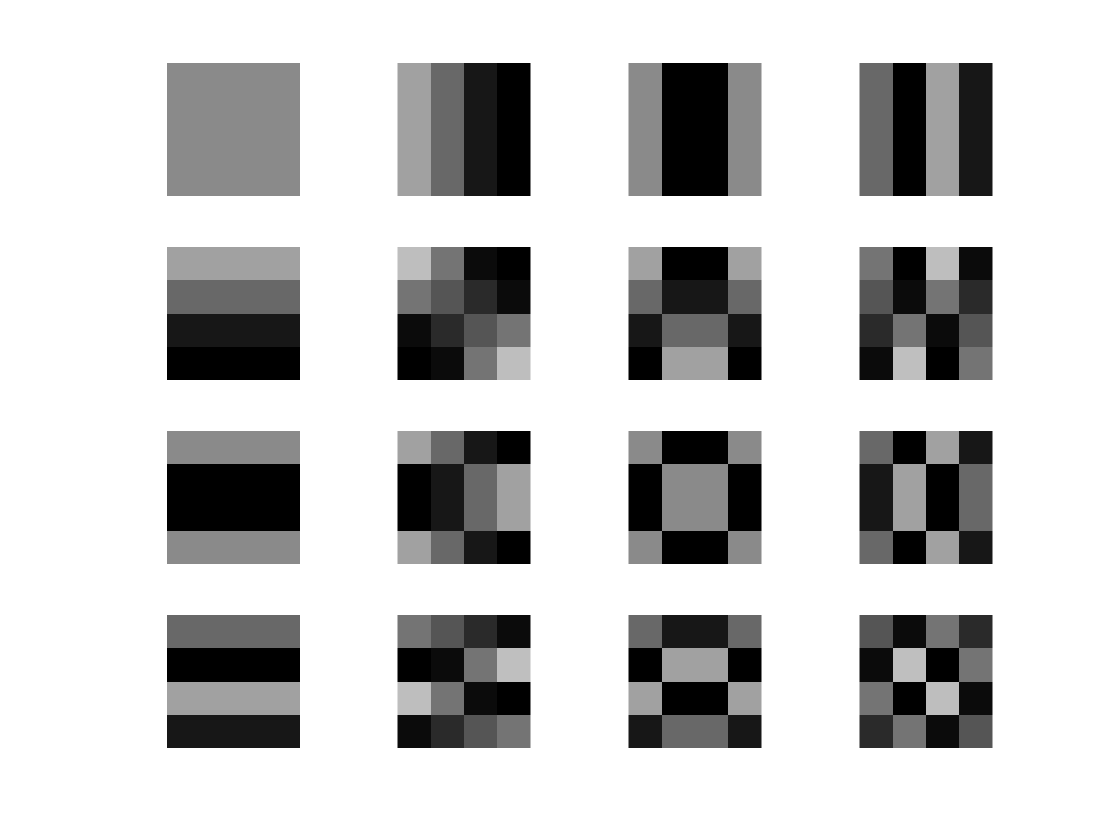

figure(2)
adj = max(abs(C(:)))^2; % 輝度調整用
for iRowV=1:nRows
    for iRowH=1:nRows
        basisVecV = C(iRowV,:).';
        basisVecH = C(iRowH,:).';
        B=kron(basisVecV,basisVecH.'); % 基底画像        
        B=uint8(127*(B/adj+0.5));        % 輝度調整
        subplot(nRows,nRows,nRows*(iRowV-1)+iRowH);
        imshow(B);
    end
end

© Copyright, Shogo MURAMATSU, All rights reserved.